# Teorema fundamental del cálculo 

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

 Una conexión profunda entre el cálculo diferencial e integral es la relación entre [funciones de acumulación](matlab:open('./Riemann.mlx')) y [funciones derivadas](https://www.mathworks.com/matlabcentral/fileexchange/99249-calculus-derivatives). 

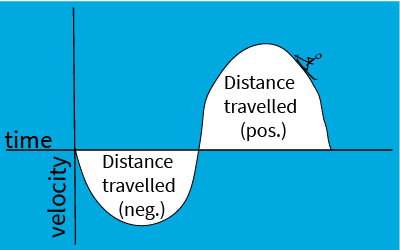

El área geométrica bajo una curva corresponde a la acumulación total del producto de los valores seguidos a lo largo de cada eje. En esta imagen, la velocidad multiplicada por el tiempo es distancia. 

** Antes de comenzar: **

Este live script está diseñado para usarse con el código oculto. En la pestaña ** View ** de la barra de herramientas de MATLAB, en la sección ** View **, seleccione ** Hide Code**. Alternativamente, seleccione ** Hide Code ** usando el ícono   en la parte superior derecha del panel Live Editor. 

 Aunque el código está oculto, cierta interactividad requiere familiaridad con MATLAB. Si necesita más instrucción, considere realizar [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea gratuito de 2 horas que enseña los conceptos básicos de MATLAB.

 Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se agotan. 

##  Teorema fundamental del cálculo, forma derivada 

 Sea $\displaystyle g(x) = \int_a^x f(t)\; dt$. Entonces 

 
$$\frac{d}{dx}\left[g(x)\right] = \frac{d}{dx}\left[\int_a^x f(t)\; dt\right]$$
                                                   

 
$$= \lim_{\epsilon \to 0}\frac{\int_a^{x+\epsilon}f(t)\; dt - \int_a^{x}f(t)\; dt}{\epsilon}$$
               

       
$$=\lim_{\epsilon \to 0} \frac{\int_{x}^{x+\epsilon}f(t)\;dt + \int_a^{x}f(t)\; dt - \int_a^x f(t)\; dt}{\epsilon}$$


              
$$=\lim_{\epsilon \to 0}\frac{\int_x^{x+\epsilon}f(t)\; dt}{\epsilon} = \lim_{\epsilon \to 0} \frac{f(x)\cdot (x+\epsilon-x)}{\epsilon} = f(x)$$


figure
clear f
syms t
f(t) =  t^2;
a = -2;
x = 3;

Para considerar un límite como $\epsilon \to 0$ , es importante considerar valores tanto positivos como negativos de `epsilon`. Para facilitar una aproximación cercana a cero, el control deslizante le permite establecer el exponente $n$ en la expresión $\epsilon = 10^n$ de modo que el control deslizante presente valores de aproximadamente 1,26 a 1e-8. 

EpsNeg = false;    EpsExp = 0;
epsilon = (-1)^EpsNeg*10^(EpsExp);
tAll = -5:.01:5;
try
    plot(tAll,f(tAll),"-",SeriesIndex="none")
catch
    plot(tAll,f(tAll),"k-")
end
ax = gca;
cmap = colororder;
hold on
if a <= x
    % Si la integración es de izquierda a derecha, colorea el área base en azul
    tVals = a:.01:x;
    % ColChoice = "#0072BD";
    ColChoice = cmap(1,:);
else
    % If the integration is right-to-left, color the base area in orange
    % and print a warning
    tVals = x:.01:a;
    % ColChoice = "#D95319";
    ColChoice = cmap(2,:);
    warning("Estás invirtiendo la dirección de la integración de izquierda a derecha a derecha a izquierda")
end
leftmax = min(a,x);
rightmin = max(a,x)+.1;

 Utilice estos controles para ampliar su región de interés: 

xleft = -5;
xright = 5;
 
% Corrige el color del área extra para que sea morado (neg) o dorado (pos)
if EpsNeg
    ColeChoice = cmap(4,:); %#ok<UNRCH>
else
    ColeChoice = cmap(3,:);
end
% ColeChoice = "#EDB120";
yVals = f(tVals);
tpeVals = linspace(x,x+epsilon,50);
ypeVals = f(tpeVals);
BaseArea = area(tVals,yVals,"FaceColor",ColChoice);
ExtraArea = area(tpeVals,ypeVals,"FaceColor",ColeChoice); %#ok<NASGU>
xlim([xleft xright])
fxVal = double(vpa(subs(f,x)));
AreaVal = double(vpa(int(f,t,x,x+epsilon)))/epsilon;
%intfVal = int(f,t,x,x+eps);
TopyVal = ax.YLim(2)+1/20*(ax.YLim(2)-ax.YLim(1));
BottomyVal = ax.YLim(1)-1/10*(ax.YLim(2)-ax.YLim(1));
LeftxVal = xleft+.1*(xright-xleft);
MidxVal = (xleft+xright)/2;
BottomxVal = xleft+.4*(xright-xleft);
text(LeftxVal,TopyVal,"$f(x) = $"+fxVal,"Interpreter","latex")
text(MidxVal,TopyVal,"$\left(\int_x^{x+\epsilon} f(t)\; dt\right)/\epsilon =$ "+AreaVal,"Interpreter","latex")
text(BottomxVal,BottomyVal,"$\epsilon = $"+epsilon,"Interpreter","latex")
hold off

  ** Pruebe **. 

-  ¿Qué sucede con el componente amarillo de su gráfico cuando reduce el tamaño de épsilon? ¿Qué notas sobre los valores de $f(x)$ y $\displaystyle \left(\int_x^{x+\epsilon}f(t)\; dt\right)/\epsilon$? 

-  ¿Qué sucede con el componente amarillo de su gráfico cuando considera un valor negativo de épsilon en lugar de uno positivo? ¿Qué notas acerca de los valores de $f(x)$ y $\displaystyle \left(\int_x^{x+\epsilon}f(t)\; dt\right)/\epsilon$? 

-  ¿Por qué crees que esto se llama la forma derivada del Teorema Fundamental del Cálculo? 

## Teorema fundamental del cálculo, forma antiderivada 

$\displaystyle F(x) = C+ \int_{-\infty}^x f(t)\; dt$ es la cantidad total acumulada desde el principio de los tiempos hasta el punto $x$ más una constante arbitraria $C$. Entonces el monto total acumulado entre $t=a$ y $t=b$ es 


$$\int_a^b f(t)\; dt = \int_{-\infty}^b f(t)\; dt - \int_{-\infty}^a f(t)\; dt = \left(C+ \int_{-\infty}^b f(t)\; dt\right) - \left(C+ \int_{-\infty}^a f(t)\; dt\right) = F(b)-F(a).$$


 Es decir, el monto acumulado entre $a$ y $b$ es el monto total que se acumuló desde el principio de los tiempos hasta el tiempo $b$ menos todo lo que se había acumulado desde el principio de tiempo hasta $a$. 

figure
syms t
f(t) = sin(t);
a = -2;
b = 1;
C = 0;
AreaFlag = false;
if ~exist("tAll","var")
    tAll = -5:.01:5;
end
F(t) = int(f,t);
FAVal = double(subs(F,a)+C);
FBVal = double(subs(F,b)+C);
try
    plot(tAll,f(tAll),"-",SeriesIndex="none")
catch
    plot(tAll,f(tAll),"k-")
end

ax = gca;
hold on
if a <= b
    % Si el área se acumula a la derecha de a, colorea el área en azul
    tVals = a:.01:b;
    ColChoice = cmap(1,:);
%    ColChoice = "#00a9e0";
else
    % Si la integración se elimina a la izquierda de a, colorea el área de naranja
    tVals = b:.01:a;
    ColChoice = cmap(2,:);
%    ColChoice = "#004b87";
end
% Arreglar el color extraArea para que sea morado.
ColeChoice = cmap(4,:);
% ColeChoice = "#7730ba";
yVals = f(tVals);
tpeVals = -5:.01:min(a,b);
ypeVals = f(tpeVals);
OverlapArea = area(tVals,yVals,"FaceColor",ColChoice);
if ~AreaFlag
    ExtraArea = area(tpeVals,ypeVals,"FaceColor",ColeChoice);
end
TopyVal = ax.YLim(2)+1/20*(ax.YLim(2)-ax.YLim(1));
BottomyVal = ax.YLim(1)-1/10*(ax.YLim(2)-ax.YLim(1));
LeftxVal = ax.XLim(1)+.1*(ax.XLim(2)-ax.XLim(1));
MidxVal = (ax.XLim(1)+ax.XLim(2))/2;
BottomxVal = ax.XLim(1)+.4*(ax.XLim(2)-ax.XLim(1));
text(LeftxVal,TopyVal,"$F(b) = $"+FBVal,"Interpreter","latex")
text(MidxVal,TopyVal,"$F(a) = $ "+FAVal,"Interpreter","latex")
text(BottomxVal,BottomyVal,"$F(b)-F(a) = $"+double(int(f,a,b)),"Interpreter","latex")
plot([a a],[min(yVals) max(yVals)],"r-")
plot([b b],[min(yVals) max(yVals)],"r-")
xNL = ["a = "+a "b = "+b "-5" "0" "5"];
[xNameVals,idxA,~] = unique([a b -5 0 5]);
xNameLabels = xNL(idxA);
xticks(xNameVals);
xticklabels(xNameLabels);
hold off

  ** Pruebe **. 

-  Cambie el valor de $a$ y/o $b$. ¿Qué sucede con el área si $a=b$ ? ¿Qué pasa si $a>b$? ¿O $a < b$? ¿Qué pasa con el valor de $F(b)-F(a)$? 

-  Cambia el valor de $C$. ¿Qué pasa con los valores y la trama? 

-  Selecciona y anula la selección de "¿Mostrar solo el área resultante?" casilla de verificación. ¿Qué pasa con tu trama? 

## Practique integrales definidas aleatorias 

  ** Pro-tip **. La sintaxis de MATLAB es 7 `*t^(2/3)` para $7t^{2/3}$. La variable que uses en la solución es importante, al igual que el uso apropiado de paréntesis y operadores de multiplicación. 

% Borrar variables que pueden reutilizarse en otras partes de este módulo.
clear MyFun VarChoice                             
syms t r x z C                       % Declarar variables simbólicas
VarOpts = [t r x z];                 % Definir la lista de variables a utilizar en los problemas.
ErrorCount = 0;                      % Inicializar un recuento de errores
TotDefProbs = 0;                     % Inicializar un recuento del total de problemas intentados
TotAttempts = 0;                     % Inicializar un recuento del total de soluciones ofrecidas
AdjustCount = 0;                     % Conservar los recuentos si el usuario vuelve a enviar una solución
LastFive = zeros(1,5);               % Inicializar una matriz para registrar los últimos cinco resultados de la solución
 
disp("Valores inicializados para la Práctica de Antiderivadas.")
disp("Si la integral no existe, usa DNE. "+newline+...
    "Si la integral diverge hacia infinito positivo o negativo, " + newline + ...
    "usa Inf o -Inf, según corresponda.") 

% Compruebe si la sección anterior se ha ejecutado
% Si no, proporcione una advertencia. Si es así genera un problema.
if ~exist("TotDefProbs","var")
    warning("Debes inicializar los valores antes de poder generar un problema.")
else
    [MyFun,VarChoice,bds] = GenProbType(VarOpts);  % genProbType está definido en Funciones auxiliares
    % genProbType configura una variable y genera una función aleatoria
    TotDefProbs = TotDefProbs+1;     % Aumentar el recuento total de problemas intentados.
end
                                    % Run this section 

% Compruebe si la sección anterior se ha ejecutado
% Si no, proporcione una advertencia. Si es así genera un problema.
if ~exist("TotDefProbs","var")
    warning("Debes inicializar los valores antes de poder generar un problema.")
elseif TotDefProbs == 0
    warning("You must generate a problem before you can solve a problem.")
else
MyAnswer = str2sym("0");     % Solución definida por el usuario, valor predeterminado 0
TotAttempts = TotAttempts + 1;       % Recuento de actualizaciones del total de intentos de solución
[LastFive,ErrorCount,TotAttempts,AdjustCount] = ResubmissionCheck(TotAttempts,TotDefProbs, ...
    AdjustCount,MyFun,VarChoice,bds,MyAnswer,ErrorCount,LastFive);
% resubmissionCheck se define en Funciones auxiliares
% resubmissionCheck registra el intento y proporciona comentarios adecuados
end
                           % Run this section

 Una vez que haya completado suficiente práctica, realice un seguimiento de los resultados generales de su práctica aquí: 

 
AnalyzeResults(TotDefProbs,ErrorCount,TotAttempts,AdjustCount,LastFive)

### Aplicación de práctica 

Puede practicar en la aplicación Tarjetas de Cálculo. Puede iniciar la aplicación haciendo clic en la imagen a continuación. Debe configurar el tipo de problema como "Integrales definidas" en la sección Integrales. La aplicación se abrirá en una nueva ventana. 

[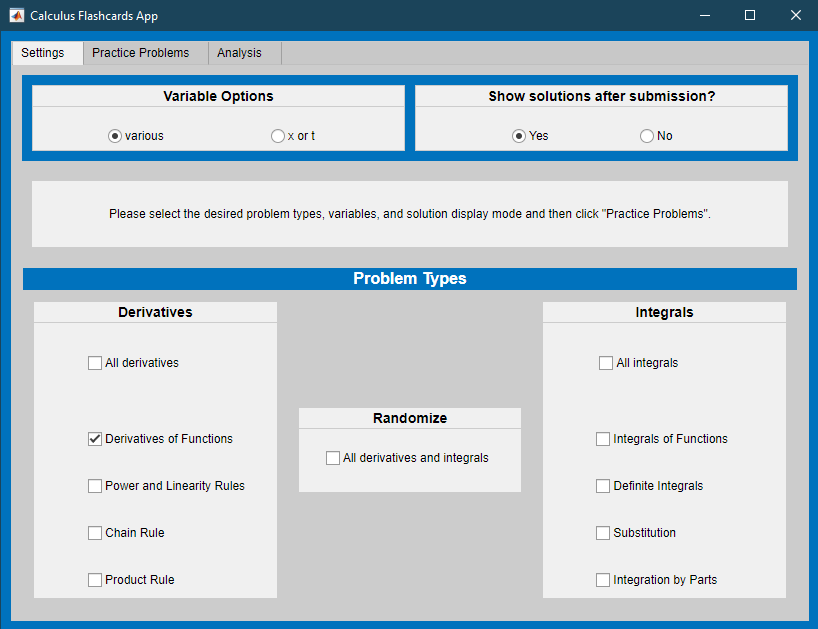](matlab: TarjetasDeCalculo)

 
TarjetasDeCalculo

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

## Funciones auxiliares locales 

Si desea ver los detalles del código, seleccione la pestaña** View **y cambie a **Output inline**. Como alternativa, seleccione **Output inline** usando el ícono   en la parte superior derecha del panel Live Editor.  

** Practicar funciones de generación de problemas **

 Construir un problema para mostrar 

function [myFun,varChoice,bds] = GenProbType(varOpts)
% genProbType configura una variable y genera una función aleatoria
%
% Entradas: varOpts es una matriz de posibles variables
% Salidas: myFun es una función simbólica
% varChoice es la variable independiente
% [a, b] son los límites de la integral definida, si requerido

% Seleccione aleatoriamente una variable del conjunto varOpts
varChoice = varOpts(randi([1 length(varOpts)],1));

% Utilice genFunDiff para generar funciones simples
% genFunDiff se define en Funciones auxiliares
% Las entradas a genFunDiff son la variable varChoice, un rango de valores
% entre los cuales seleccionar coeficientes y un valor que indica cuál Las advertencias
% ya se han impreso durante la generación del problema.
        syms f(x) x 
        [f(x),~] = GenFunDiff([1 10],x,[1 10],0);
        myFun = f(varChoice);
        bds = randi([-3,4],[1 2]);
        a = bds(1); %#ok<NASGU>
        b = bds(2); %#ok<NASGU>
        % Mostrar el problema integral
        disp("Calculate the integral:")
        displayFormula("F(varChoice) == int(myFun,varChoice,a,b)")
end

 Generar funciones aleatorias apropiadas 

function [myFunc,type] = GenFunDiff(bds,var,range,prevFuncType)
syms f(t)                    % Crear una función simbólica f(t)
params = randi(bds,[1 4]);   % Elija aleatoriamente los valores de los parámetros
shift = randi([0 max(abs(bds))],1); % Elija aleatoriamente un turno que puede ser 0
sgns = randi([0 1],[1 3]);   % Elija aleatoriamente signos +/-
type = randi(range,1);


% Para facilitar la lectura, cree los parámetros a,b,c yd.
a = (-1)^sgns(1)*params(1);
b = (-1)^sgns(2)*params(2);
c = max(params(3),params(4));  % c > 0, solo se usa como denominador
d = (-1)^sgns(3)*shift;

switch type
    case 1
        f(t) = a*t^b+c*t^d;
    case 2
        f(t) = a*t^b+t^(d/c);
    case 3
        f(t) = t^a+c*t^b+t^d;
    case 4
        f(t) = t^a+c*t^b+d;
    case 5
        f(t) = a*t^(b);
    case 6
        f(t) = a*t^(b/c);
    case 7
        f(t) = a*log(abs(b)*t);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Recuerda que log(x) es la notación " + ...
                "para un logaritmo natural en MATLAB.")
        end
    case 8
        f(t) = a*exp(b*t);
        if prevFuncType ~= 8
        disp("Recuerda que exp(x) es la notación para e^x en MATLAB.")
        end
    case 9
        f(t) = a*sin(b*t);
    case 10
        f(t) = a*cos(b*t);
    case 11
        f(t) = a*log(ceil(c/4)*t);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Recuerda que log(x) es la notación " + ...
                "para un logaritmo natural en MATLAB.")
        end
    case 12
        f(t) = a*t^c;
    case 13
        f(t) = a*sin(b*t+d)*exp(b*t);
    case 14
        f(t) = a*cos(b*t+d)*exp(b*t);
end
myFunc = f(var);
end

 Manejar envíos 

function [lastFive,errorCount,totAttempts,adjustCount] = ResubmissionCheck(totAttempts,totProbs, ...
    adjustCount,myFun,varChoice,bds,myAnswer,errorCount,lastFive)
if sum(totAttempts > (totProbs + adjustCount))
    % Check if this is a resubmission after the solution has been provided
    % If so, provide feedback but do not record in errorCount or lastFive
    % If not, update the values of lastFive and errorCount using check1
    adjustCount = totAttempts-totProbs;
   [lastFive,errorCount] = Check1(myFun,varChoice,bds,myAnswer,errorCount,lastFive);

elseif sum(totAttempts < (totProbs + adjustCount))
    % Check if this is a submission after the generation of multiple problems that were skipped
    % If so, add the skipped problems to errorCount and adjust the totAttempts
    % to compensate. Explain to the user that skipped problems count as incorrect.
    numSkipped = totProbs + adjustCount - totAttempts;
    errorCount = errorCount + numSkipped;
    totAttempts = totProbs + adjustCount;
    for k = 1:length(totProbs)
        if numSkipped(k) < 5
            lastFive(k,:) = [lastFive(k,1+numSkipped:5),zeros(1,numSkipped)];
        else
            lastFive(k,:) = zeros(1,5);
        end
        if sum(numSkipped) > 1
        disp("Los "+sum(numSkipped)+" problemas generados sin intentos de solución " + ...
            "han sido incluidos en el conteo de errores.")
        disp(" ")
    elseif sum(numSkipped) == 1
        disp("El problema generado sin un intento de solución ha sido " + ...
            "incluido en el conteo de errores.")
        end
        [lastFive,errorCount] = Check1(myFun,varChoice,bds,myAnswer,errorCount,lastFive);
    end
else
        [lastFive,errorCount] = Check1(myFun,varChoice,bds,myAnswer,errorCount,lastFive);
end
end

 Verificar que la solución enviada sea correcta 

function [lastFive,errorCount] = Check1(myFunc,myVar,bds,myAnswer,errorCount,lastFive)
% check1 genera respuestas correctas integrando y actualizando
% errorCount y lastFive
%
% Entradas: myFunc es la función simbólica para diferenciar 
% o integrar myVar es la variable independiente myAnswer es 
% la función o número de prueba simbólico errorCount es un número 
% entero que rastrea el total de intentos incorrectos *-- -* 
% lastFive es un vector que rastrea los últimos cinco intentos 
% Salida: correctAnswer es una función simbólica que es la solución 
% a probType aplicada a myFunc(myVar) con bds
tol = 1e-3;
correctAnswer = int(myFunc,myVar,bds);
if isequal(myAnswer,str2sym("DNE"))
    myAnswer = nan;
end
lastFive(1:4) = lastFive(2:5);
disp("Cuando se simplifica, esta función es: ")
disp(myAnswer)
if correctAnswer == myAnswer
    disp("Esa respuesta es correcta.")
    lastFive(5) = 1;
elseif isnan(correctAnswer) && isnan(myAnswer)
    disp("Esa respuesta es correcta. Esta integral no existe.")
    lastFive(5) = 1;
elseif isinf(correctAnswer) && isinf(myAnswer)
    if sign(real(correctAnswer))==sign(myAnswer)
        disp("Esa respuesta es correcta. La integral diverge hacia:")
        disp(correctAnswer)
        lastFive(5) = 1;
    else
        disp("Tienes razón en que la integral diverge, pero no en la dirección.")
        disp("La integral diverge hacia: ")
        disp(correctAnswer)
        lastFive(5) = 0;
    end
elseif ~isreal(myAnswer)
    disp("Tu respuesta debería ser un número real finito. Por favor, inténtalo de nuevo.")
elseif abs(double(myAnswer-correctAnswer))<tol
    disp("Esa respuesta está redondeada. Un valor más preciso es:")
    disp(correctAnswer)
    lastFive(5) = 1;
else
    disp("Eso es incorrecto. Recuerda ser preciso. La respuesta correcta es:");
    a = bds(1); %#ok<NASGU>
    b = bds(2); %#ok<NASGU>
    displayFormula("int(myFunc,myVar,a,b)==correctAnswer")
    % respuesta correcta %#ok<NOPRT>
    errorCount = errorCount + 1;
    disp("Por favor, inténtalo de nuevo con un nuevo problema.")
    lastFive(5) = 0;
end
end

 Analizar los resultados y dar retroalimentación 

function AnalyzeResults(totProbs,errorCount,totAttempts,adjustCount,lastFive)
% analiceResults proporciona retroalimentación en el caso de un solo tipo de problema
% totProbs, errorCount, totAttempts y ajustaCount son números enteros
% lastFive es un vector
overallRight = (1 - sum(errorCount)/sum(totProbs))*100;
if sum(totAttempts) > sum(totProbs)
    % Si el usuario ha vuelto a enviar después de ver la solución, responda
    disp("¿Por qué estás reenviando después de saber la solución?")
    disp("Los reenvíos no se incluyen en tus estadísticas.")
    if sum(adjustCount) > 1
        % Si el usuario está reenviando repetidamente, anímalo a usar
        % este generador de problemas como se pretende, comenzando de nuevo
        disp("Has reenviado " + sum(adjustCount) + " veces.")
        disp("Por favor, considera reiniciar el conteo usando el botón `Inicializar Valores'.")
    end
end
if totProbs >= 5
    lastCorrect = sum(lastFive);
    % If more than 5 problems have been attempted, provide grammatically
    % appropriate feedback on success rates
    if lastCorrect > 1
str = compose("La tasa de éxito general es %.1f%% en %i problemas totales \n\n" + ...
            "De los últimos cinco, %i fueron correctos.",overallRight,totProbs,lastCorrect);
    elseif lastCorrect == 1
        str = compose("La tasa de éxito general es %.1f%% en %i problemas totales \n\n" + ...
            "De los últimos cinco, uno fue correcto.",overallRight,totProbs);
    elseif lastCorrect == 0
        str = compose("La tasa de éxito general es %.1f%% en %i problemas totales \n\n" + ...
            "De los últimos cinco, ninguno fue correcto.",overallRight,totProbs);
    end
else
    % Si se han intentado menos de 5 problemas, fomente la perseverancia.
    str = compose("La tasa de éxito general es %.1f%% en %i problemas totales \n\n" + ...
        "Por favor, haz al menos cinco problemas.",overallRight,totProbs);
end
disp(str)
end